# Problem 2.2b

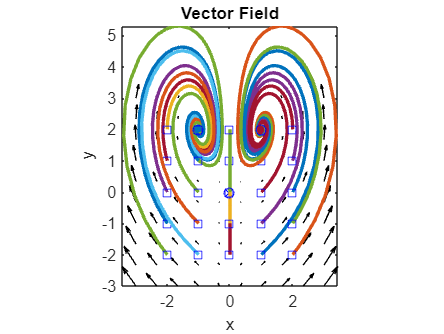

close all; clc

% Create vector field with solutions
x = linspace(-3,3,10);
y = linspace(-3,3,10);
[X,Y] = meshgrid(x,y);
DX = 2*X - X.*Y;        
DY = 2*X.^2 - Y;
quiver(X,Y,DX,DY,'k');
xlabel('x')
ylabel('y')
axis tight equal;
title("Vector Field")

hold on;

% plot equilibrium points
for y0 = [0 0; 1 2; -1 2]'
    [~, ys] = ode45(@f,[0 10],y0);
    plot(ys(:,1),ys(:,2),'bx')
end

% plot trajectories
for x0 = -2:1:2
    for y0 = -2:1:2
        [~, ys] = ode45(@f,[0 10],[x0 y0]);
        plot(ys(:,1),ys(:,2),'-','LineWidth',2);
        plot(ys(1,1), ys(1,2),'bs');
        plot(ys(end,1), ys(end,2),'bo');
    end
end
hold off;

% linearize the system automatically
syms x y
disp('Jacobian')

Jacobian


J = jacobian([2*x-x*y,2*x^2-y],[x,y])

$$J = \left(\begin{array}{cc} 2-y & -x\\ 4\,x & -1 \end{array}\right)$$


% evaluate jacobian at equilibrium points
Legend=cell(3,1);
iter = 1;
for eq = [0 0; 1 2; -1 2]'
    x0 = eq(1);
    y0 = eq(2);
    disp('===========================')
    disp(['Eq Point: ', num2str([x0 y0])])
    A = subs(J,[x y], [x0 y0])
    lambda = eig(A)
    
    plot(real(lambda),imag(lambda),'x','MarkerSize',10); hold on
    Legend{iter} = num2str([x0 y0]);
    iter = iter + 1;
end

Eq Point: 0  0


$$A = \left(\begin{array}{cc} 2 & 0\\ 0 & -1 \end{array}\right)$$

$$lambda = \left(\begin{array}{c} -1\\ 2 \end{array}\right)$$

Eq Point: 1  2


$$A = \left(\begin{array}{cc} 0 & -1\\ 4 & -1 \end{array}\right)$$

$$lambda = \left(\begin{array}{c} -\frac{1}{2}-\frac{\sqrt{15}\,\mathrm{i}}{2}\\ -\frac{1}{2}+\frac{\sqrt{15}\,\mathrm{i}}{2} \end{array}\right)$$

Eq Point: -1  2


$$A = \left(\begin{array}{cc} 0 & 1\\ -4 & -1 \end{array}\right)$$

$$lambda = \left(\begin{array}{c} -\frac{1}{2}-\frac{\sqrt{15}\,\mathrm{i}}{2}\\ -\frac{1}{2}+\frac{\sqrt{15}\,\mathrm{i}}{2} \end{array}\right)$$

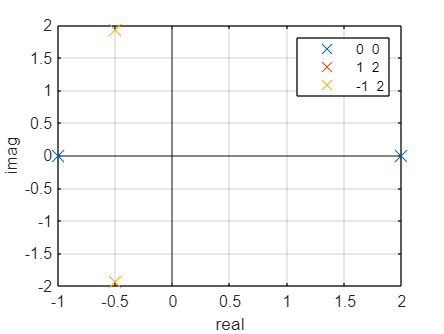

axis on
grid on
yline(0)
xline(0)
legend(Legend)
xlabel('real')
ylabel('imag')
hold off

function [y_dot] = f(~,y)
y_dot(1,:) = 2*y(1)-y(1).*y(2);
y_dot(2,:) = 2*y(1).^2 - y(2);
end